# Visualize Slices of Volumetric Data

Show volumetric data along slice planes defined by function.

## Initialize a 3-D Function and Slice Planes

Create a 3-D volume defined by $v = xe^{-x^2-y^2-z^2}$, where *x*, *y*, and *z* range from $\left\lbrack -2,2\right\rbrack$. Create slice planes orthogonal to the *x*-axis at the values $-1\ldotp 2$, $0\ldotp 8$, and 2 and orthogonal to the *z*-axis at the value `0`. Do not create any slice planes that are orthogonal to the *y*-axis by specifying an empty array.

[X,Y,Z] = meshgrid(-4:.2:4);
V = X.*exp(-X.^2-Y.^2-Z.^2);
xslice = [-1.2,0.8,2];   
yslice = [];
zslice = 0;

## Plot Basic Slices

Create the slice plot by providing the `slice `command with the volume axis and function followed by the slice plane coordinates.

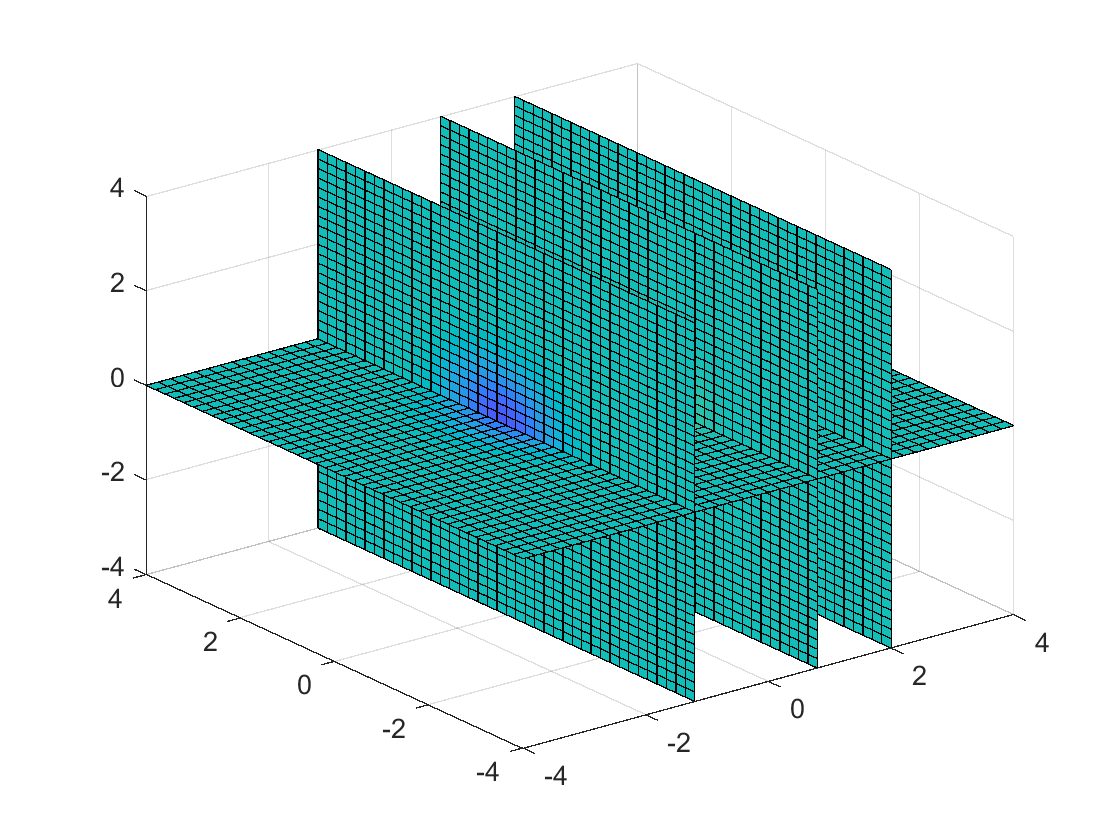

slice(X,Y,Z,V,xslice,yslice,zslice)

## Customizations

### Set Axes Limits

Axes limits can be defined to improve visualization around a specific region of the plot as the default scaling may be too wide

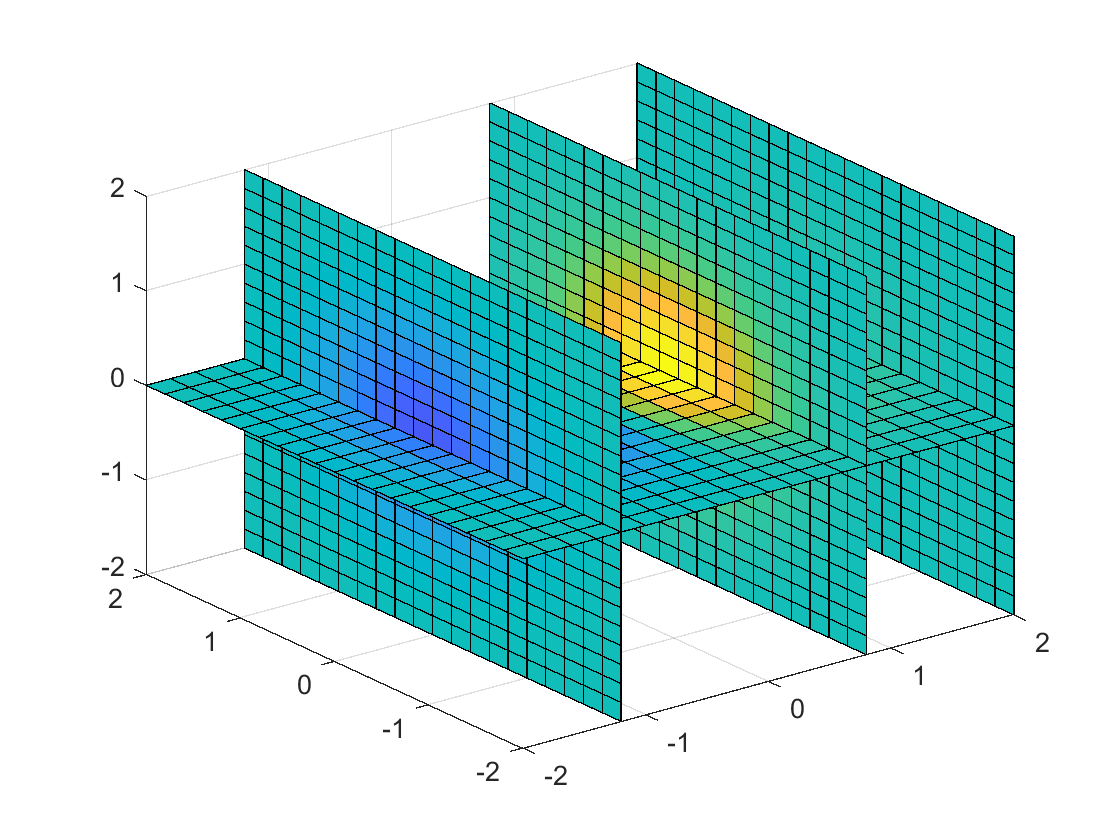

xlim([-2 2])
ylim([-2 2])
zlim([-2 2])

### Plot Advanced Slices

To create a more complex slice shape, a surface plot can be defined in` x`,` y`, and z. Create a meshgrid matrix for `x` and `y `defined from $\left\lbrack -2,2\right\rbrack$. Define the `z `set of slice coordinates as $z=x^2 -y^2$, creating a saddle shape. Plot the slice on the same volume data.

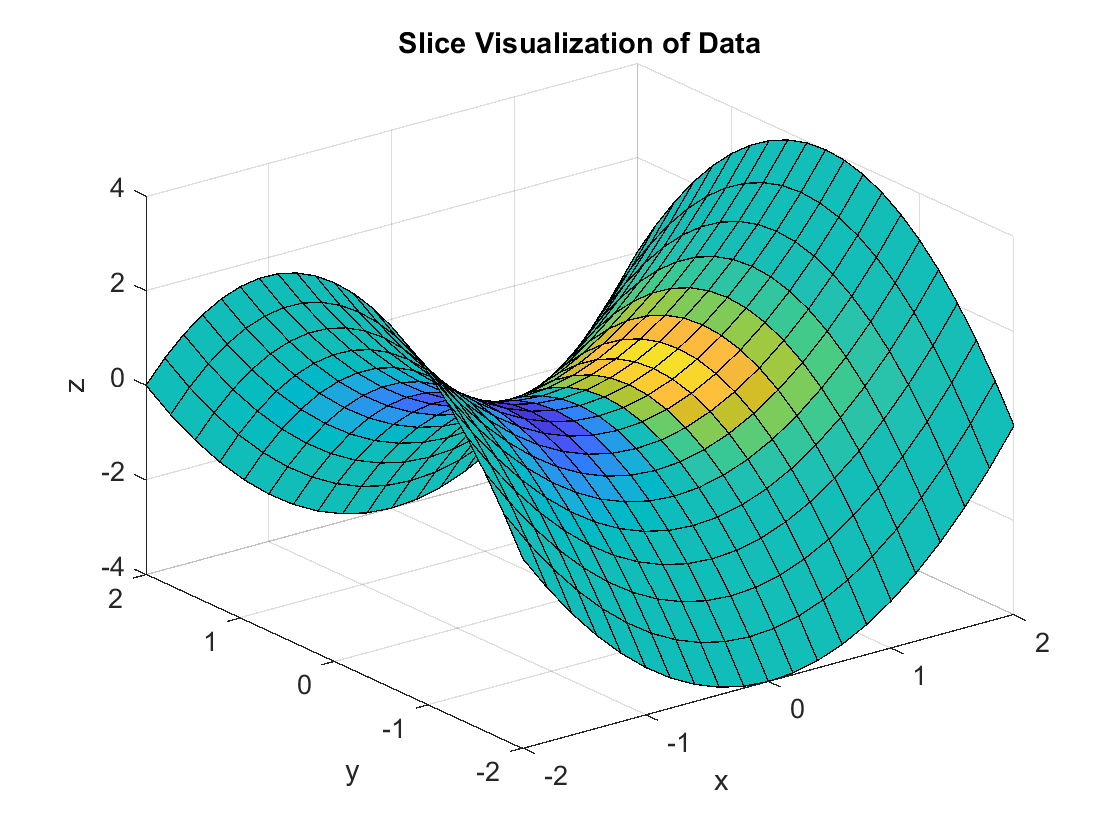

figure
[xsurf,ysurf] = meshgrid(-2:0.2:2);
zsurf = xsurf.^2-ysurf.^2;
sl = slice(X,Y,Z,V,xsurf,ysurf,zsurf);
title('Slice Visualization of Data')
xlabel('x')
ylabel('y')
zlabel('z')

## Additional Information

### Get All Slice Properties

Graphics objects in MATLAB have many properties. To see all the properties of a slice, uncomment the following code

% get(sl)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[slice](https://www.mathworks.com/help/matlab/ref/slice.html)